# DATA EXPLORATION

1. Data structure exploration 2. Visualization

## Load depedencies

addpath '../../data/test alpha 5s'          % Data, Not: the data has been bandpass filtered, descripiton is in the README.md
addpath '../../tools/spectral'              % tools
    
ALLEEG = load('5sopen_close.mat').ALLEEG;   % EEGLAB format
sig = ALLEEG.data;

## Visualization

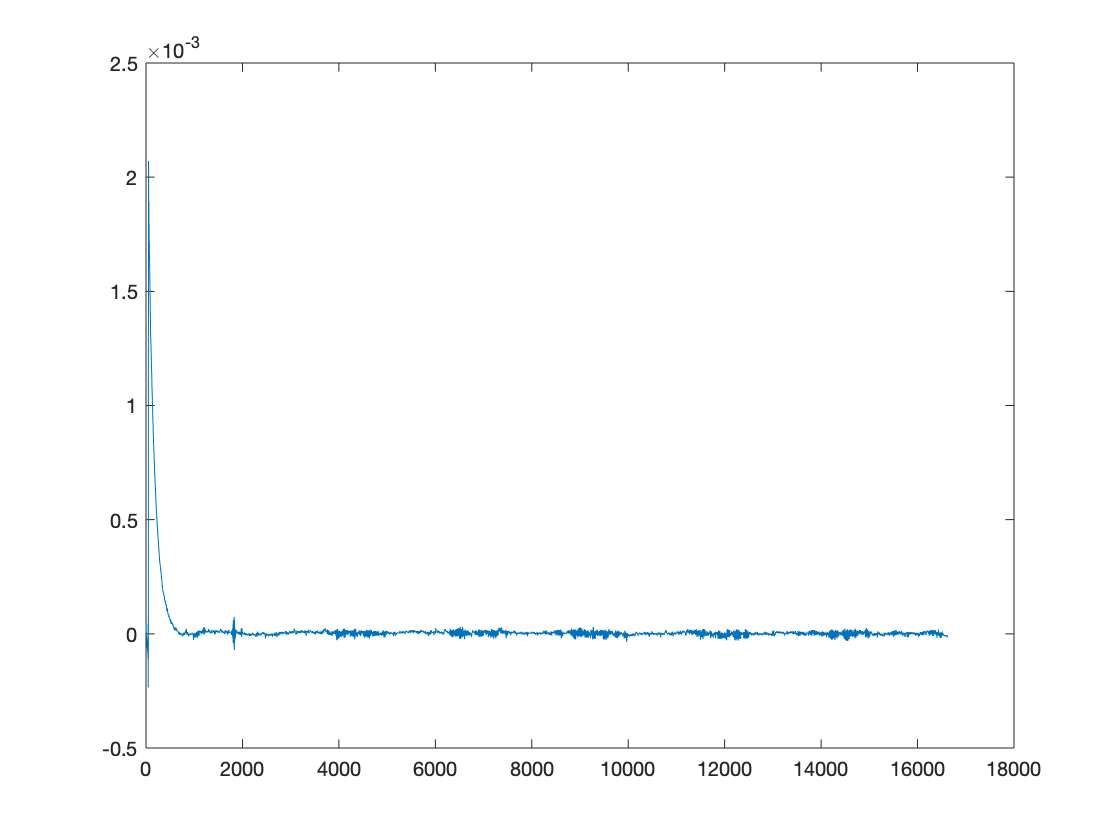

figure;
plot(sig)

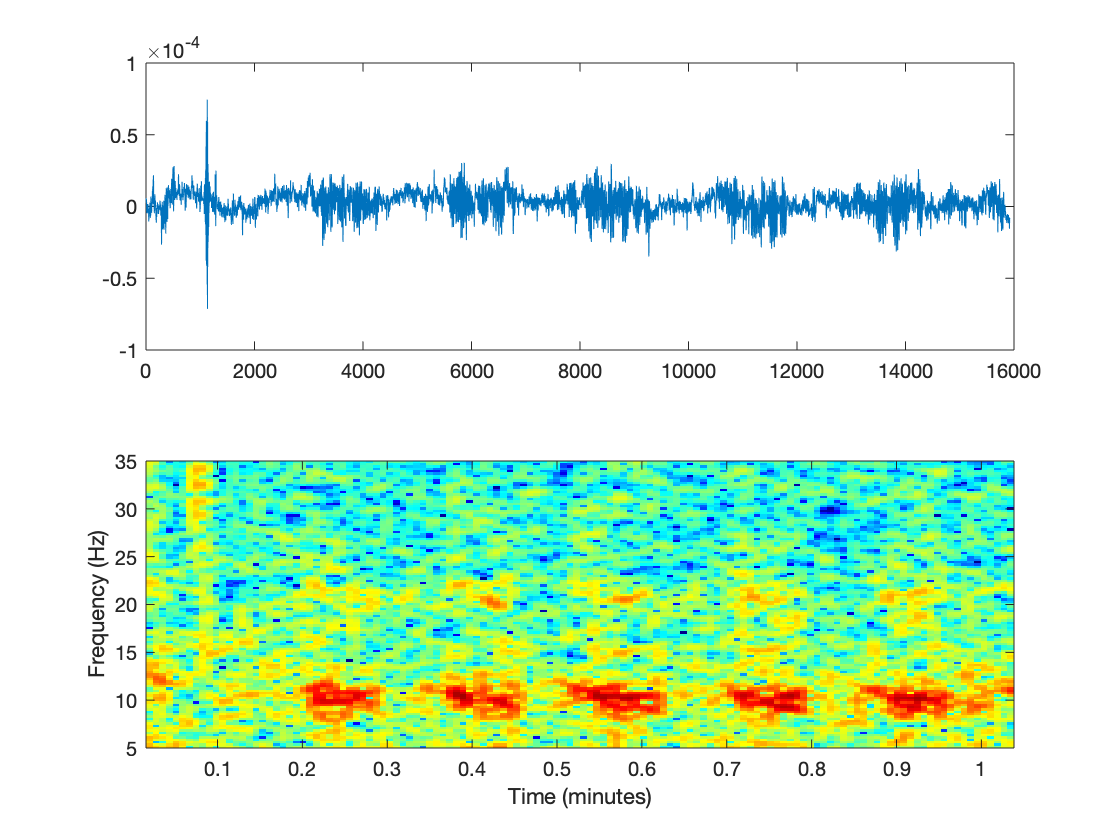


% First few seconds of the recording is often artifacts.
% Let's plot again, without first few seconds
figure;
start = 700;    
subplot(2,1,1), 
plot(sig(start:end))    % raw signal

ax = subplot(2,1,2); 
plot_spectrogram(sig, start, 1, ax), colormap(jet(256)); colorbar('Off');   % Spectrogram of the signal

## Explore signals of open/close eyes

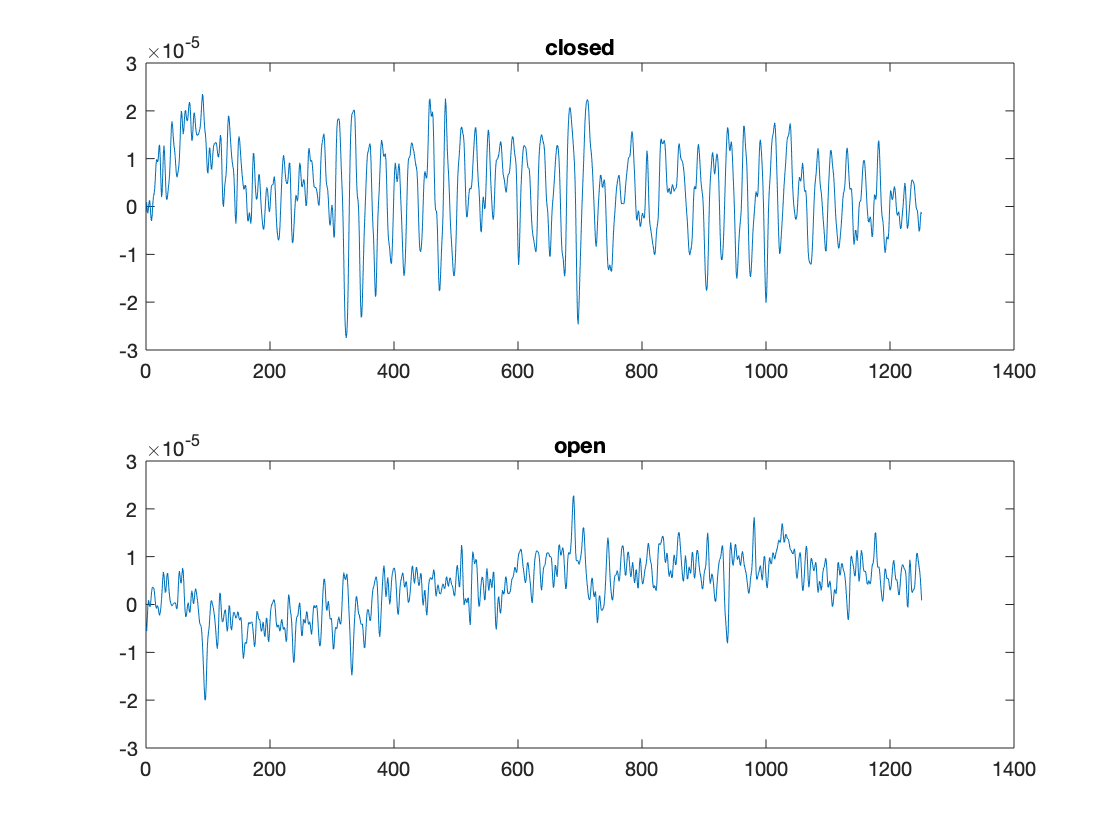

events = ALLEEG.event;
event1 = events(1).latency; % odd: closed, even: open
Fs = ALLEEG.srate;          % sampling frequency
duration = Fs*5;            % duration of eacch event = 5 seconds

closed_sample = sig(event1:(event1+duration));
open_sample = sig((event1-duration):event1);

figure;
subplot(2,1,1), plot(closed_sample), title('closed')
subplot(2,1,2), plot(open_sample), title('open')

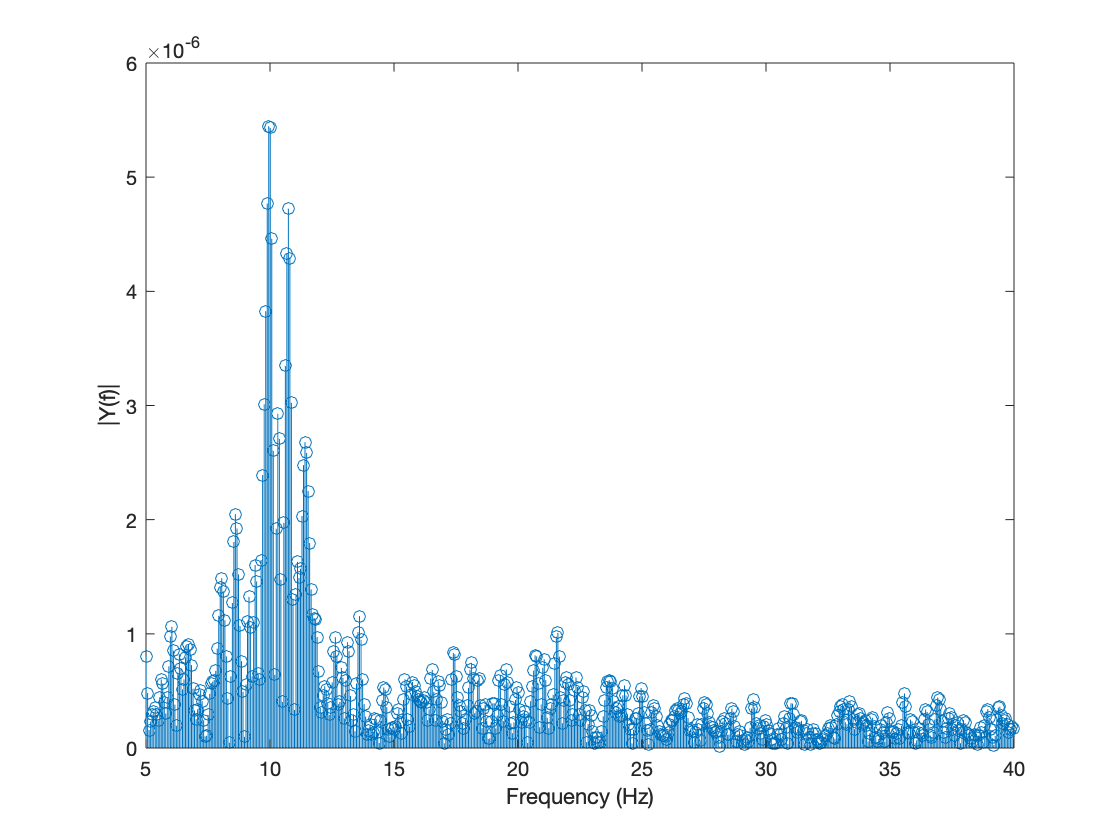


% Spectral components when the eyes are closed
figure;
plotFFT(closed_sample, Fs, gca);

## Visualize event locations in spectrogram

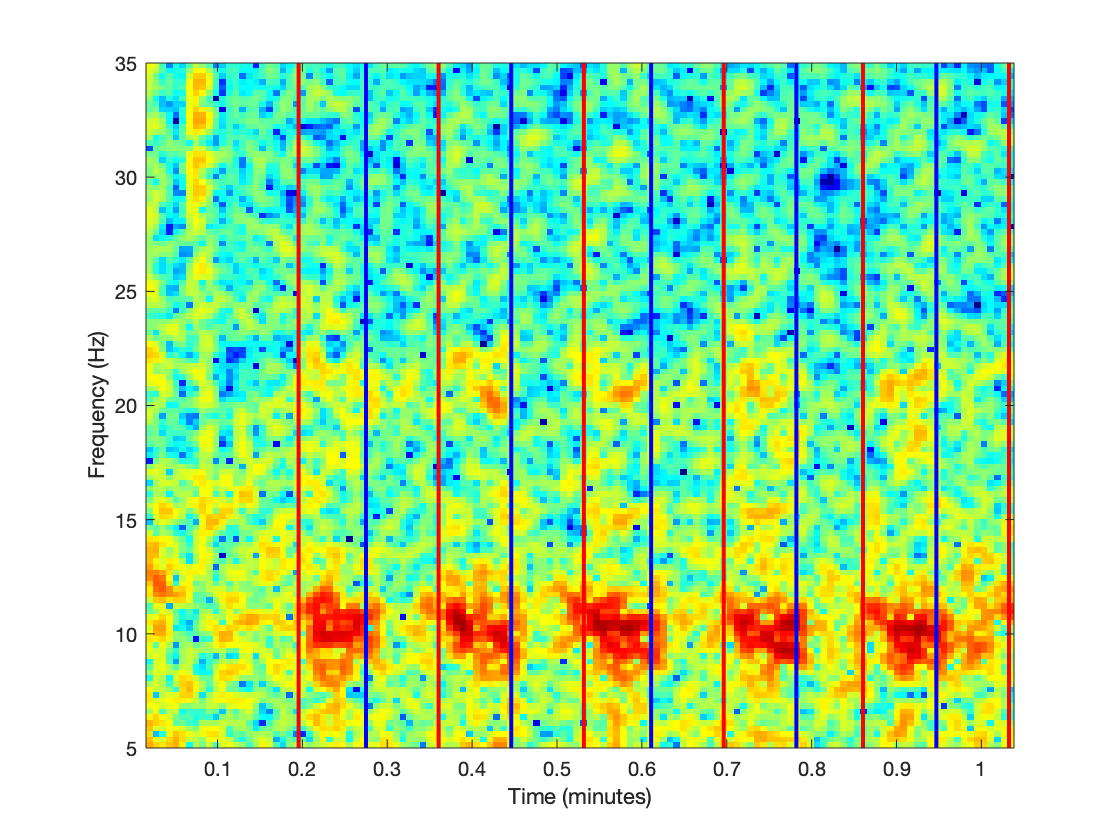

figure;
hax = subplot(1,1,1);
plot_spectrogram(sig, start, 1, hax); 

numevent = length(events); colorbar('Off'), colormap(jet(256))

events_close = [];
events_open = [];

for i = 1:numevent
    event = events(i).latency;
    event_norm = (event - start)/Fs/60;     % offseted by start, normalized by Fs and minutes
    x = [event_norm, event_norm];
    y = [0, 35];
    if mod(i,2) == 0    % even = OPEN (BLUE)
        line(hax, x,y, 'Color', 'blue', 'LineWidth', 2)
        events_open = [events_open, event];
    else                % odd = CLOSE (RED)
        line(hax, x,y, 'Color', 'red', 'LineWidth', 2)
        events_close = [events_close, event];
    end
end

## Customized exploration

------- Enter your code here ------